Binarizing a concrete crack image. The imbinarize function uses Otsu's method for finding the optimal threshold value.

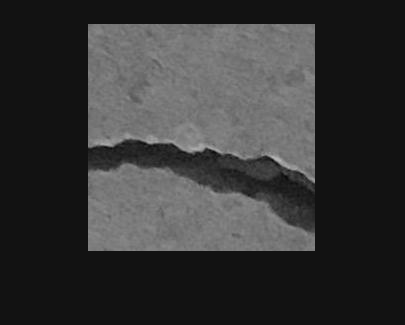

img = im2gray(imread("00187.jpg"));
imshow(img)

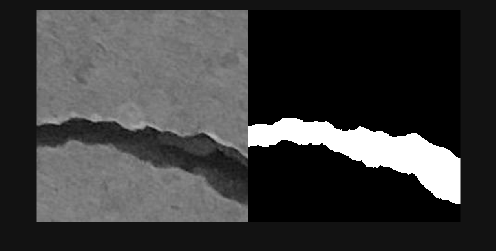


BW = imbinarize(img);
BW = ~BW;
montage({img, BW});

nnz(BW)

ans = 7846


graythresh(img)

ans = 0.3255

graythresh(img) * 255

ans = 83

Creating a mask using the binarized image

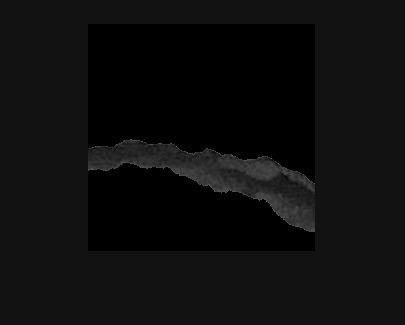

maskedImg = img;
maskedImg(~BW) = 0;
imshow(maskedImg)

Otsu´s method doesn't always work well. For example, it fails to binarize correctly in this image: 

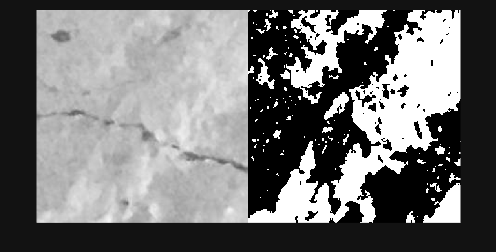

img = im2gray(imread("00051.jpg"));
BW = imbinarize(img);
montage({img, BW})

graythresh(img)

ans = 0.7451

Trying this with a numeric slider for finding the optimal value yields the following result: 

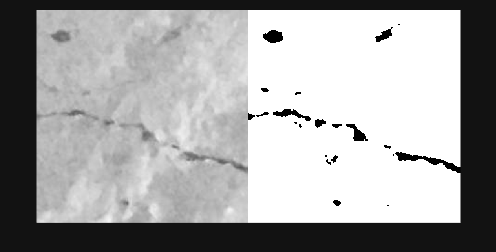

img = im2gray(imread("00051.jpg"));
BW = imbinarize(img, 0.63);
montage({img, BW})

We can apply adapting thresholding to make the thresholding value adopt different values depending on the local average intensity

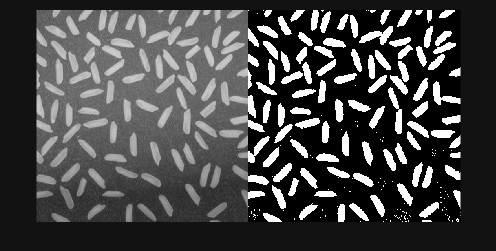

img = imread("rice.png");
BW = imbinarize(img, "adaptive");
montage({img, BW})

Segmentation doesn't always need to be binary. For example, we can segment different regions of interest in an image. 

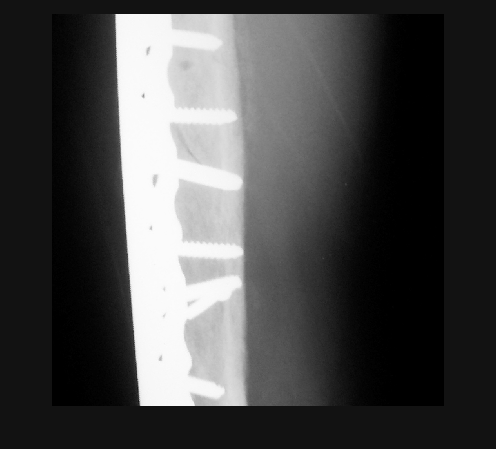

img = imread("armxray.png");
imshow(img);

threshValues = multithresh(img, 3)

threshValues = 1×3 uint8 row vector
    54   147   223


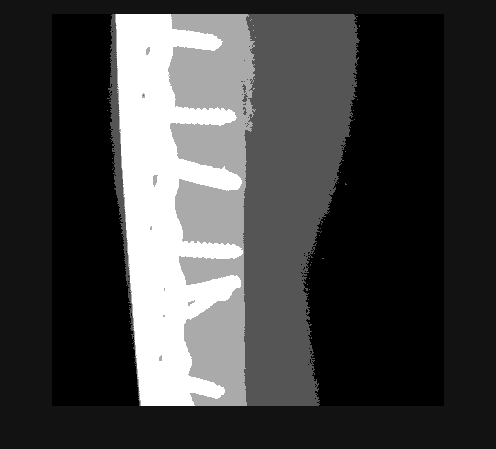

labels = imquantize(img, threshValues);
imshow(labels, [])